## Replicando resultados de McMillen (2003)

El modelo a estimar un modelo urbano monocéntrico como:


$$y_i =\mathrm{b0}+\mathrm{b1}\text{ }{\mathrm{DCBD}}_i ,$$


donde $y_i$ es el logaritmo natural de la densidad del empleo, y ${\mathrm{DCBD}}_i$ es  la distancia al centro comercial de la ciudad. La distancia $x_i$ tiene un rango de $\left(-50,50\right)$ con incrementos de $0\ldotp 1001$. El centro comercial se ubica en la distancia $x_i =0$, y ${\text{DCBD}}_i =\left|x_i \right|$, los valores de los parámetros del experimento son: $\mathrm{b0}=1\ldotp 5$ y $\text{b}1=-0\ldotp 05$.

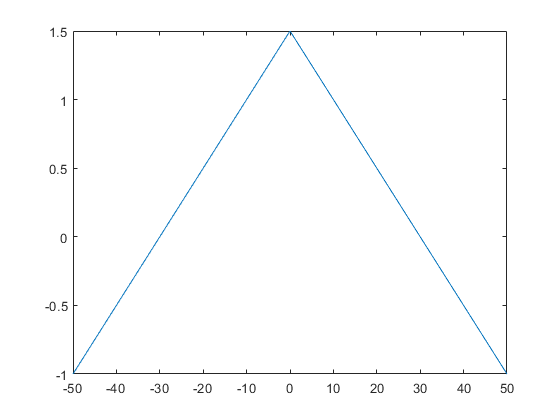

n = 1000;
b0 = 1.5; b1 = -0.05; b2 = -0.15; b3 = 0.9;
x = (-50:0.1001:50)';
DCBD = abs(x);
log_employ_dens = 1.5 - 0.05*DCBD;
plot(x, log_employ_dens)

Ahora McMillen supone que existe un subcentro, localizado en la distancia $x_i =-30$, confinado a un rango de distancias $-36<x_i <-30$. La densidad del empleo alcanza un máximo local y luego declina: ${\text{D}\mathrm{SUB}}_i =\left|{-30+x}_i \right|$, se supone que 

%xloc = (-36:0.1001:-24)';
SUB = zeros(length(x),1);
for i = 1:length(x)
    if x(i)>-36
        if x(i)<-30
            SUB(i,1)= 1;
        end
    end
end
DSUB = SUB.*abs(-30-x);
log_employ_dens = 1.5-0.05*DCBD-0.15*DSUB+0.9*SUB;
plot(x, log_employ_dens)

XX = [ones(n,1) DCBD DSUB SUB]; 
betas = [b0 b1 b2 b3]';

% R2=var(Xbetas)/[var(Xbetas)+var(u)]
% R2=0.8 -> var(u) = var(Xbetas)/4
sd_u = sqrt(var(XX*betas)/4);

% Matriz espacial
Wbin = zeros(n);
for i = 1:n
    for j = 1:n
        if (abs(i-j)==1)
            Wbin(i,j)=1;
        end
    end
end
W = normw(Wbin);

%% Monte Carlo
% Generamos el entorno para guardar los resultados Monte Carlo
% Tiempo: 3 min aprox.
MC = [];
count = 0;
reps = 100;
sistem = XX*betas; 
tic
for xx=0:2
    X = XX(:,1:(4-xx));
    for i=1:reps
        u = normrnd(0,sd_u,[1,n])';
        y = sistem + u;
        count = count+1;
        res1 = moran(y,X,W);
        res2 = lmlag(y,X,W);
        res3 = lmlag_robust(y,X,W);
        res4 = lmerror(y,X,W);
        res5 = lmerror_robust(y,X,W);
        res6 = ols(y,X);
        s = size(X,2);
        MC(count,1) = s;
        MC(count,2) = res1.prob;
        MC(count,3) = res2.prob;
        MC(count,4) = res3.prob;
        MC(count,5) = res4.prob;
        MC(count,6) = res5.prob;
        MC(count,7) = res6.rsqr;
    end
end
toc
%%
% Pct rechazo modelo correcto
B=MC(any(MC==4,2),:);
BB=mean(B(:,2:6)<0.05).*100;

meanR2 = median(B(:,7))
% Pct rechazo modelo Mal-especificado 1: 3 X's (const,DCBD,DSUB) 
C=MC(any(MC==3,2),:);
CC=mean(C(:,2:6)<0.05).*100;

% Pct rechazo Misspecified model 2: 2 X's (const,DCBD)
% Modelo usado en McMillen (2003)
D=MC(any(MC==2,2),:);
DD=mean(D(:,2:6)<0.05).*100;

fprintf('___________________________________________\n');
fprintf('          Tabla de McMillen (2003) \n');

___________________________________________


fprintf('     Pctje rechazo: H0 no-autocor. esp.\n');

          Tabla de McMillen (2003) 


fprintf('-------------------------------------------\n');

     Pctje rechazo: H0 no-autocor. esp.


fprintf('       Model  k   I Moran   LMerror \n');

-------------------------------------------


fprintf('       True   4   %05.2f     %05.2f\n', [BB(1) BB(4)]);

       Model  k   I Moran   LMerror 


fprintf('       Miss1  3   %05.2f     %05.2f\n', [CC(1) CC(4)]);

       True   4   10.00     09.00


fprintf('       Miss2  2   %05.2f     %05.2f\n', [DD(1) DD(4)]);

       Miss1  3   75.00     72.00


fprintf('___________________________________________\n');

       Miss2  2   89.00     89.00


fprintf('\n');

___________________________________________


fprintf('\n');

fprintf('_________________________________________________________\n');

fprintf('      Tabla de McMillen ampliada a tests robustos \n');

_________________________________________________________


fprintf(' Porcentaje de rechazo: H0 no-autocorrelación espacial \n');

      Tabla de McMillen ampliada a tests robustos 


fprintf('---------------------------------------------------------\n');

 Porcentaje de rechazo: H0 no-autocorrelación espacial 


fprintf('Model  k   I Moran   LMlag    RLMlag   LMerror   RLMerror \n');

---------------------------------------------------------


fprintf('True   4   %05.2f     %05.2f    %05.2f    %05.2f     %05.2f\n', BB);

Model  k   I Moran   LMlag    RLMlag   LMerror   RLMerror 


fprintf('Miss1  3   %05.2f     %05.2f    %05.2f    %05.2f     %05.2f\n', CC);

True   4   10.00     09.00    08.00    09.00     09.00


fprintf('Miss2  2   %05.2f     %05.2f    %05.2f    %05.2f     %05.2f\n', DD);

Miss1  3   75.00     73.00    13.00    72.00     12.00


fprintf('_________________________________________________________\n');

Miss2  2   89.00     89.00    05.00    89.00     05.00


fprintf('\n');

_________________________________________________________
